# Model Ear Canal

You model the physical human ear canal using two cascaded cylindrical tubes with thermo-viscous losses, connected in series with the `Ear Drum Impedance` component. The `Ear Drum Impedance` is a composite block that models the response of an averaged human ear drum. See the `EarDrumSimulator` example model for more details.

## Open Model

Open the ear canal model.

model = "EarCanal";
open_system(model);

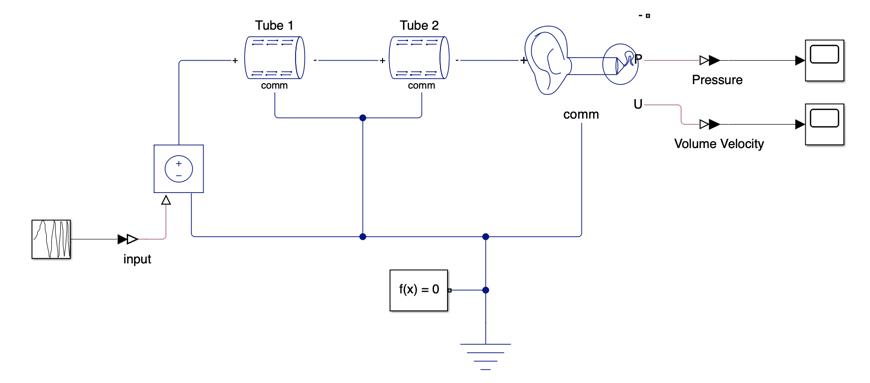

The human ear canal is not an uniform cylindrical tube. The  model simulates the system using two cylindrical tubes with different dimensions. The dimensions are provided as follows:

- Tube #1: radius = 0.005 m, length = 0.003 m.

- Tube #2: radius = 0.0035 m, length = 0.0095 m.

Tube #1 corresponds to the opening at the outer ear. Tube #2 is connected to the ear drum impedance.

The detailed configurations of each tube are shown in the figure below. 

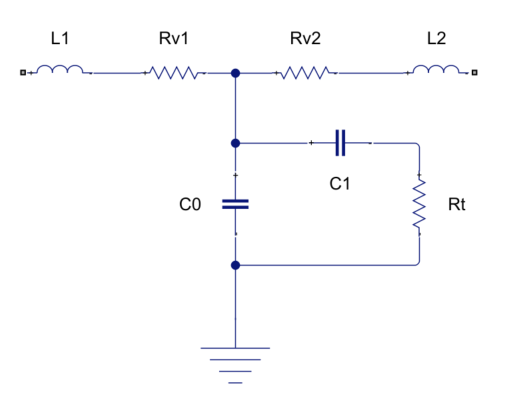


$$$L_1 =L_2 = \frac{\rho l}{2A}$$$



$$$R_{v1}=R_{v2}=\frac{8\pi\rho\nu l}{2A^2}$$$



$$$C_0=\frac{V}{\rho c^2}$$$



$$$C_1 =C_0(\gamma-1)$$$



$$$R_t=\frac{\rho^2 c^2 C_p}{8\pi \kappa(\gamma-1)l}$$$


Where:

- $$\rho$$ is the density of air $$1.21 kg/m^3$$.

- $$\nu$$ is the viscosity of air $$15.68\times10^{-6} m^2/s$$.

- $$c$$ is the sound speed in air $$343m/s$$.

- $$\gamma$$ is the ratio of specific heat for air.

- $$\kappa$$ is the thermal conductivity of air $$0.0257 W/mK$$.

- $$C_p$$ is the specific heat of air at constant pressure $$1.01 \times10^3 kJ/kgK$$.

- $ $l$$ is the length of the tube.

- $$A$$ is the cross sectional area of the tube.

- $$V$$ is the volume of the tube.

## Linearize Model

This example sets the input perturbation point and output measurement point for analysis in the frequency domain instead of the time domain. Extracting the real-time simulation outputs and performing Fourier Transform also returns the same results. The "Ear Drum Impedance" enables both pressure and volume velocity measurements at the termination. 

In this example, you analyze the pressure response.

Set the model linearizing points.

io(1) = linio("EarCanal/Chirp Signal",1, "input");      % input perturbation
io(2) = linio("EarCanal/Pressure",1, "output");         % output pressure measurement

Use the `linearize` function to linearize the model and the `bode` function to extract the magnitude, phase, and frequency information. 

linsys = linearize(model,io);       % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                % convert radiance to frequency

Plot the results.

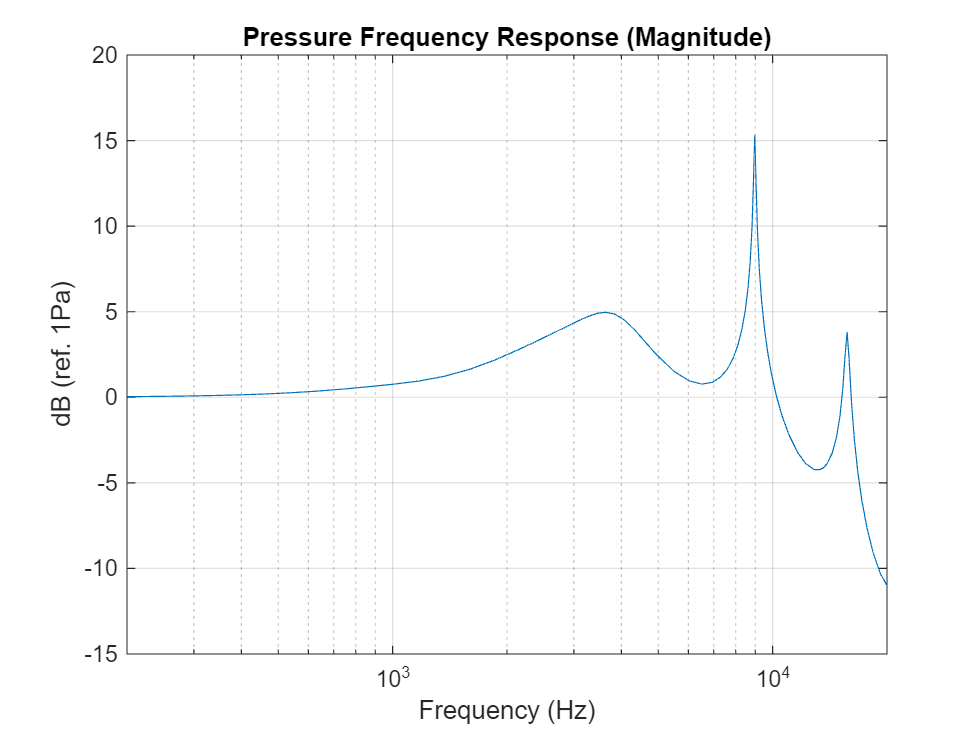

figure(1)
semilogx(freq, 10*log10(mag(:)));
xlim([200 20e3]);
title("Pressure Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("dB (ref. 1Pa)");
grid on
hold on

## Include Damping

In this section, you add additional damping, namely R1, R3, and R5, to the model and verify the change in the pressure response.

path1 = model+"/Ear Drum Impedance";         % specify component block
condition1 = "acoustic.enum.R1(2)";          % enumeration condition for including R1
condition2 = "acoustic.enum.R3(2)";          % enumeration condition for including R3
condition3 = "acoustic.enum.R5(2)";          % enumeration condition for including R5
set_param(path1,"damping1", condition1);     % set damping1 parameter to include R1 
set_param(path1,"damping3", condition2);     % set damping3 parameter to include R3 
set_param(path1,"damping5", condition3);     % set damping5 parameter to include R5 


Linearize the model and extract the results.

linsys = linearize(model,io);       % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                % convert radiance to frequency

Plot the new results.

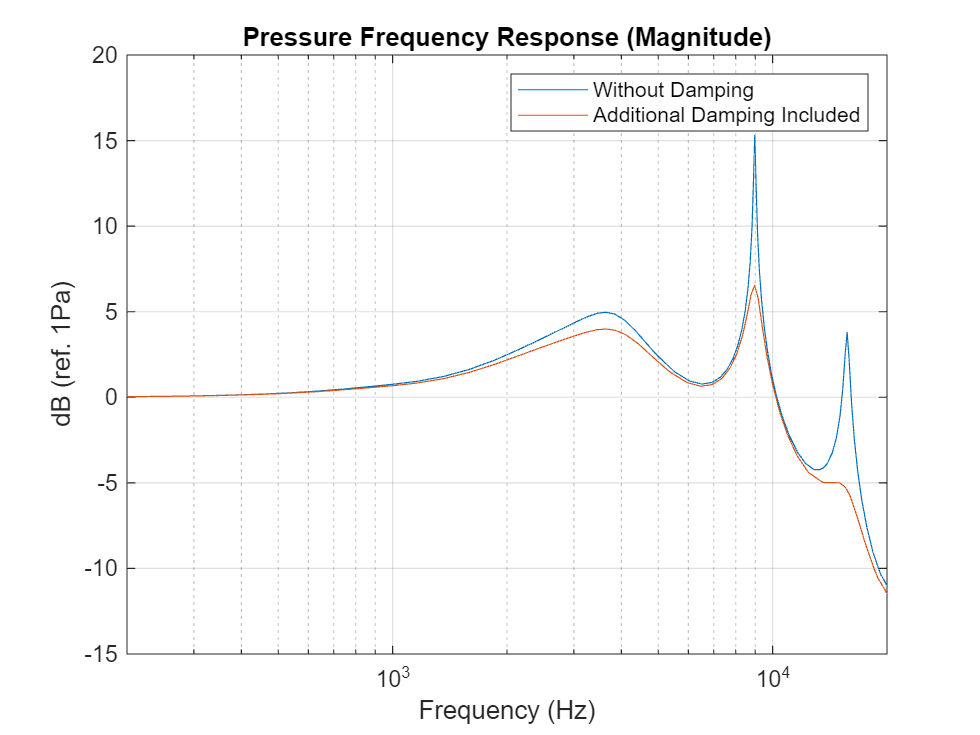

figure(1)
semilogx(freq, 10*log10(mag(:)));
legend("Without Damping", "Additional Damping Included");

## Modify Tube Length

Analyze the effect of modifying the tube length.

First, reset the damping parameters  to their origianal state.

condition1 = "acoustic.enum.R1(1)";          % enumeration condition for excluding R1
condition2 = "acoustic.enum.R3(1)";          % enumeration condition for excluding R3
condition3 = "acoustic.enum.R5(1)";          % enumeration condition for excluding R5
set_param(path1,"damping1", condition1);     % reset damping1 parameter
set_param(path1,"damping3", condition2);     % reset damping3 parameter 
set_param(path1,"damping5", condition3);     % reset damping5 parameter

Decrease the length of Tube 2 by a factor of 0.5;

path2 = model+ "/Tube 2";                  
set_param(path2,"length", "l2*0.5");  

Linearize the modified model.

linsys = linearize(model,io);     
[mag, ~, wout] = bode(linsys); 

Convert the radiance to frequency.

freq = wout./(2*pi); 

Plot the new results.

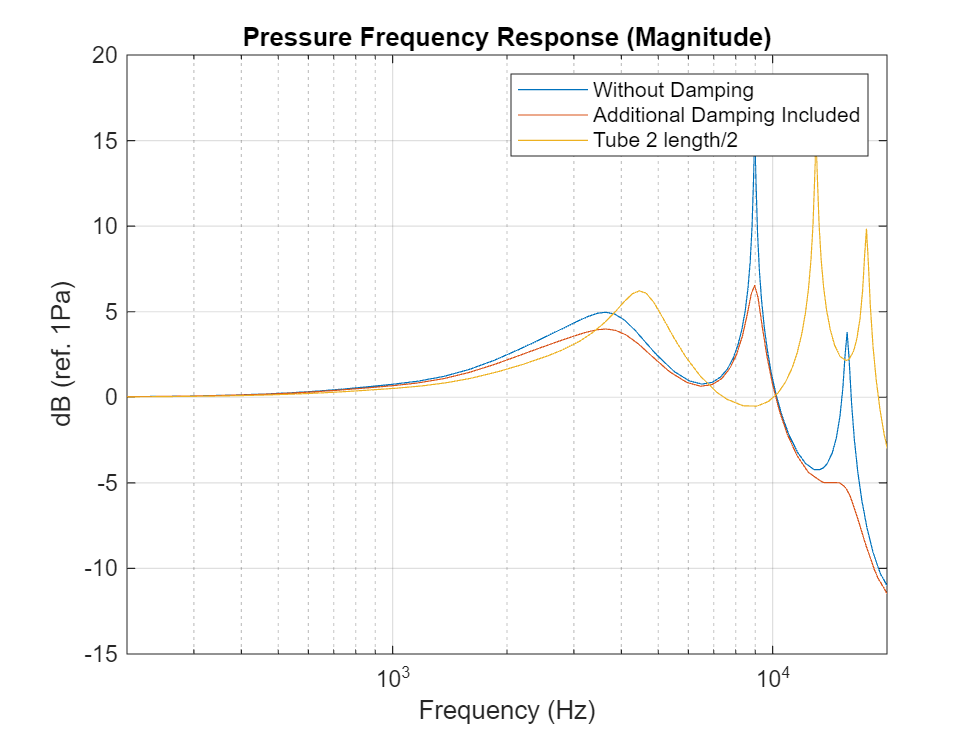

figure(1)
semilogx(freq, 10*log10(mag(:)));
legend("Without Damping", "Additional Damping Included", "Tube 2 length/2");

## Modify Tube Radius

Analyze the effect of modifying the tube radius.

First, revert the tube length to its original value.

set_param(path2,"length", "l2");

Next, double the tube radius.

set_param(path2,"a", "a2*2");

Linearize the modified system.

linsys = linearize(model,io); 
[mag, ~, wout] = bode(linsys);
freq = wout./(2*pi); 

Plot the new results.

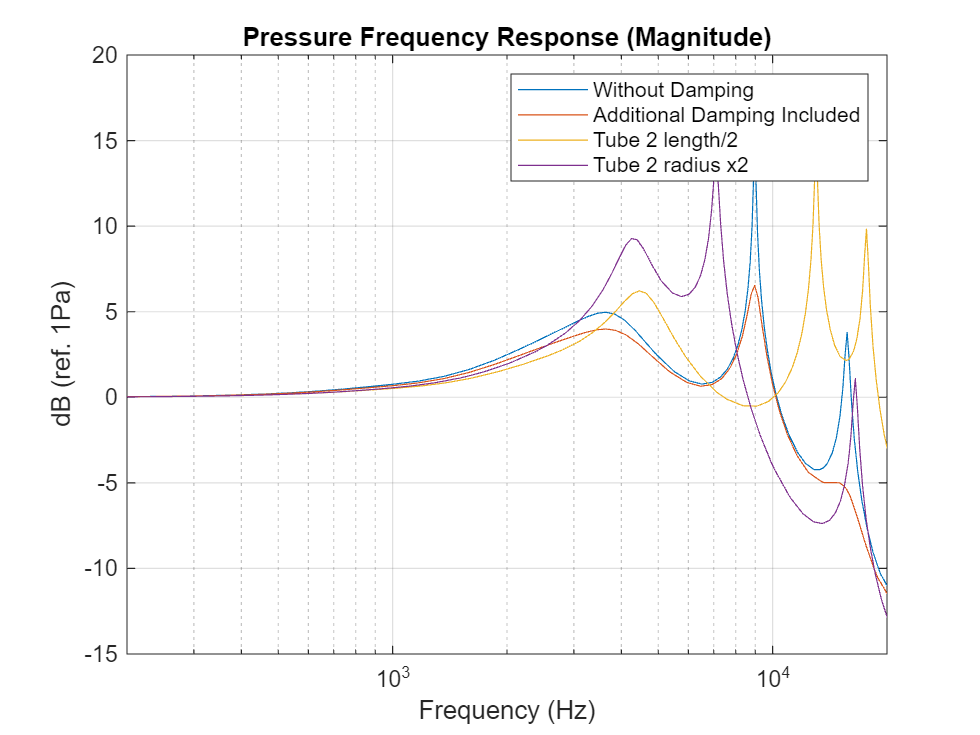

figure(1)
semilogx(freq, 10*log10(mag(:)));
legend("Without Damping", "Additional Damping Included", "Tube 2 length/2", "Tube 2 radius x2");

Close the system.

bdclose(model)

## References

- Thompson, Stephen & Gabrielson, Thomas & Warren, Daniel. (2014). Analog model for thermoviscous propagation in a cylindrical tube. The Journal of the Acoustical Society of America. 135. 10.1121/1.4861237. 

- Gazzola, Chiara & Zega, Valentina & Corigliano, Alberto & Lotton, Pierrick & Melon, Manuel. (2023). Lumped-Parameters Equivalent Circuit for Piezoelectric MEMS Speakers Modeling. 10.61782/fa.2023.0485. 

- Gazzola, Chiara & Zega, Valentina & Corigliano, Alberto & Lotton, Pierrick & Melon, Manuel. (2024). A reduced-order-model-based equivalent circuit for piezoelectric micro-electro-mechanical-system loudspeakers modeling. The Journal of the Acoustical Society of America. 155. 1503-1514. 10.1121/10.0024939. 

- Huang, Chen-Hung & Pawar, Suryappa & Hong, Zih-Jyun & Huang, Jin. (2012). Earbud-type earphone modeling and measurement by head and torso simulator. Applied Acoustics - APPL ACOUST. 73. 10.1016/j.apacoust.2011.10.007. 

*Copyright 2025 The MathWorks, Inc.*